written by Ebenezer Gnanamanickam for AE 521

This solves the following Blasius ODE to get the Blasius boundary layer profile

Blasius boundary layer ODE


$$ff^{\prime \prime}+2f^{\prime \prime \prime}=0$$


Boundary conditions


$$\eta =0 \mathrm{~then~}  f(0)=0; f(0)^\prime=0\\
\eta\rightarrow\infty, \mathrm{~then~} f(\infty)^{\prime}=1$$


The Blasius boundary layer ODE is posed as the following three couple system of ODE's. Here $y_1=f$

Therefore,


$$y_1^\prime=y_2\\
y_2^\prime=y_3\\
y_3^\prime=-\frac{y_1y_2}{2} $$


with the boundary conditions which are really an initial condition for these system of ODE's


$$y_1(0)=f(0)=0;~~y_2(0)=f^\prime(0)=0$$


We still need a boundary (initial) condition for $y_3(0)$. 

The script uses Newton's methods with an initial guess to interate on $y_3(0)$ untill the far field boundary condition $f^\prime(\infty)=1$ is satisfied. 

Note, also $\eta$ has to be large enough such that $\eta\rightarrow\infty$. 

clc; clear all; close all;
fontSize=16;
set(0,'DefaultTextInterpreter','latex','DefaultAxesLineWidth',0.5,...
    'DefaultAxesFontSize',fontSize,'DefaultFigureInvertHardCopy',...
    'on','DefaultAxesFontName','Times','DefaultLineMarkerSize',6,...
    'DefaultLineLineWidth',1.5)
set(0,'DefaultLegendInterpreter','latex',...
    'DefaultLegendFontSize',fontSize,...
    'DefaultLegendOrientation','horizontal',...
    'DefaultLegendLocation','NorthOutside',...
    'DefaultLegendNumColumns',2)

etaMax=8;
cntMax=100;
nPts=200;

% need f'(inf)=1
% used Newton Raphson to iterate to get f'(inf)=1
initGuess=0.0;
err=10;
dEta=0.0001;
cnt=0;
while err>1e-5 
    cnt=cnt+1;
    [eta,y]=ode45(@BlasiusEqn,linspace(0,etaMax,nPts),...
        [0; 0; initGuess]);
    [~,temp]=ode45(@BlasiusEqn,linspace(0,etaMax,nPts),...
        [0; 0; initGuess+dEta]);
    df=(temp(end,2)-y(end,2))/dEta;
    currGuess=initGuess;
    initGuess=initGuess+(1-y(end,2))/df;
    err=sqrt(((currGuess-initGuess)/currGuess)^2);
    if cnt>cntMax
        error=1e-8;
    end
end

% determine delta
[~,iTemp]=min(abs(y(:,2)-0.99));
eta(iTemp)

ans = 4.9045

intDeltaStar=trapz(eta,1-y(:,2))

intDeltaStar = 1.7208

intTheta=trapz(eta,y(:,2).*(1-y(:,2)))

intTheta = 0.6641


intDelta3=trapz(eta,y(:,2).*(1-y(:,2).^2))

intDelta3 = 1.0443

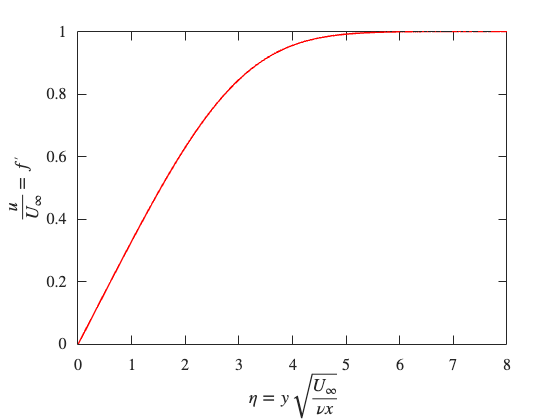


figure
plot(eta,y(:,2),'r')
xlabel('$\eta=y\sqrt{\frac{U_\infty}{\nu x}}$')
ylabel('$\frac{u}{U_\infty}=f^{\prime}$')

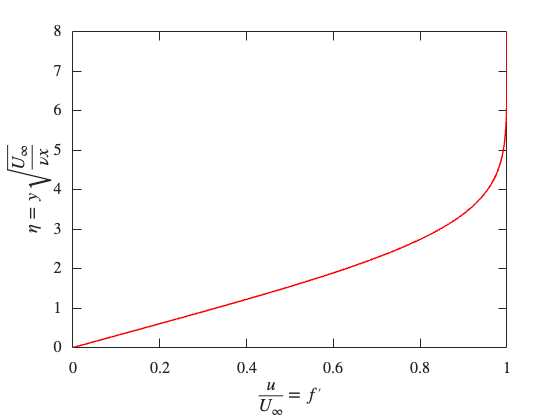

figure
plot(y(:,2),eta,'r')
ylabel('$\eta=y\sqrt{\frac{U_\infty}{\nu x}}$')
xlabel('$\frac{u}{U_\infty}=f^{\prime}$')

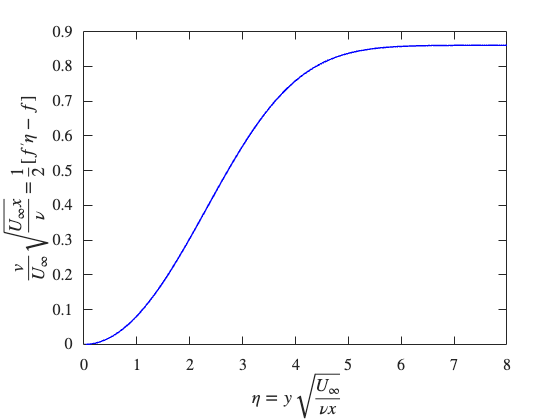


figure
plot(eta,1/2*(y(:,2).*eta-y(:,1)),'b')
xlabel('$\eta=y\sqrt{\frac{U_\infty}{\nu x}}$')
ylabel('$\frac{v}{U_\infty}\sqrt{\frac{U_\infty x}{\nu}}=\frac{1}{2}\left[f^{\prime}\eta-f\right]$')

function fBL=BlasiusEqn(eta,y)

fBL=[y(2); y(3); -y(1)*y(3)/2];

end